# Automobile Velocity Control

A self-driving car company has requested a speed controller for their new model of electric autonomous vehicles. Unlike standard cruise control systems, this speed controller must manage transitions between all velocities ranging from 0 to 25 m/s (56 mph or 90 km/hr).

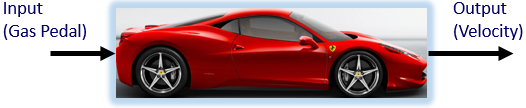

The speed controller changes a gas pedal (%) input that adjusts electrical current to the motor, creates a torque on the drive train, applies forward thrust from wheel contact on the road, and changes the velocity of the vehicle. Regenerative braking is part of this application by allowing the gas pedal to go from -50% to 100%. Decreases in velocity are also due to resistive forces. Negative velocities (backwards driving) is highly undesirable.

## Momentum Balance

A momentum balance is the accumulation of momentum for a control volume equal to the sum of forces *F* acting on the automobile.


$$\frac{d(mv)}{dt}=\sum{F}$$


with *m* as the mass in the vehicle and passengers and *v* as the velocity of the automobile. Assuming constant mass of the vehicle, a constant drag coefficient, $C_d$, and a linear gain between gas pedal position and force, the momentum balance becomes


$$m\frac{dv(t)}{dt} = F_pu(t)-\frac{1}{2}\rho AC_dv(t)^2$$


with $u(t)$ as gas pedal position (%pedal), $v(t)$ as velocity (m/s), *m* as the mass of the vehicle (500 kg) plus the mass of the passengers and cargo (200 kg), *C**d* as the drag coefficient (0.24), ρρ as the air density (1.225 kg/m3), *A* as the vehicle cross-sectional area (5 $m^2$), and $F_p$ as the thrust parameter (30 N/%pedal).

## Control System Design

A first step in controller design is to list the PV (process variable), OP (controller output), SP (controller set point), and any potential DVs (disturbance variables). The three elements that create feedback control are a sensor, actuator, and controller.

**Element / Cruise Control**

OP: Actuator / Gas Pedal Position

CV: Controller Set Point / Desired Speed (mph or km/hr)

PV: Measurement (Sensor) / Speedometer, measured velocity

DV: Disturbance variables / Hills, wind, cargo + passenger load

## Fit to First-Order Model

A first step in determining acceptable PID tuning parameters is to approximate the system response with a first-order plus dead-time (FOPDT) model. This can either be done approximately with graphical methods and a step response or more precisely with optimization. In this case, use the step response obtained from the simulation above to obtain parameters $K_p,\tau_p,$ and $\theta_p$.

tf = 60.0;                 % final time for simulation
nsteps = 61;               % number of time steps
delta_t = tf/(nsteps-1);   % how long is each time step?
ts = linspace(0,tf,nsteps); % linearly spaced time vector

% simulate step test operation
step = zeros(nsteps,1); % u = valve % open
step(11:end) = 50.0;       % step up pedal position
% passenger(s) + cargo load
load = 200.0; % kg
% velocity initial condition
v0 = 0.0;
% set point
sp = 25.0;
% for storing the results
vs = zeros(nsteps,1);
sps = zeros(nsteps,1);

% simulate with ODEINT
for i=1:nsteps-1
    u = step(i);
    % clip inputs to -50% to 100%
    if u >= 100.0
        u = 100.0;
    end
    if u <= -50.0
        u = -50.0;
    end
    [~,v] = ode45(@(t,y) vehicle(t,y,u,load),[0 delta_t],v0);
    v0 = v(end);   % take the last value
    vs(i+1) = v0; % store the velocity for plotting
    sps(i+1) = sp;

    % plot results
end

% plot results
subplot(2,1,1)
plot(ts,vs,'-b','LineWidth', 3); hold on
plot(ts,sps,'--k','LineWidth', 2); hold off
ylabel('Velocity (m/s)');
legend({'Velocity','Set Point'},'Location', 'northwest');
subplot(2,1,2);
plot(ts,step,'--r','LineWidth', 3);
ylabel('Gas Pedal');
legend({'Gas Pedal (%)'});
xlabel('Time (sec)');

## Problem Statement

viewSolution(false)

Design a controller that will achieve satisfactory performance in set point tracking over the range of requested driving velocities. Use physics-based modeling to create a suitable dynamic representation of the relationship between gas pedal position (%) and vehicle velocity. Create simulated step tests to fit to a first-order plus dead-time (FOPDT) model. Use the FOPDT model parameters $K_p,\tau_p,$ and $\theta_p$ to design a PI controller with parameters $K_c$ and $\tau_I$ (derivative time constant is zero, $\tau_D=0$). Test the controller over a range of set point changes that may be encountered in typical driving conditions. Show plots of the velocity and gas pedal position as the car achieves the desired velocity set points. Discuss how disturbances such as wind or a hill would affect the velocity and how the controller would respond.

## Vehicle Model

function dv_dt = vehicle(~,v,u,load)
    % inputs
    %  v    = vehicle velocity (m/s)
    %  t    = time (sec)
    %  u    = gas pedal position (-50% to 100%)
    %  load = passenger load + cargo (kg)
    Cd = 0.24;    % drag coefficient
    rho = 1.225;  % air density (kg/m^3)
    A = 5.0;      % cross-sectional area (m^2)
    Fp = 30;      % thrust parameter (N/%pedal)
    m = 500;      % vehicle mass (kg)
    % calculate derivative of the velocity
    dv_dt = (1.0/(m+load)) * (Fp*u - 0.5*rho*Cd*A*v^2);
end

Solution

function viewSolution(view)
if view
	disp("dy = 25;" + newline + ...
	     "du = 20;" + newline + ...
	     "Kp = dy/du;  % m/s" + newline + ...
	     "thetap = 0;" + newline + ...
	     "taup = 20;  % sec  time to get to .632 dy" + newline + ...
	     "" + newline + ...
	     "tf = 300;  % final time (s)" + newline + ...
	     "nsteps = 301;  % number of time steps" + newline + ...
	     "dt = tf/(nsteps+1);  % time of each time step (s)" + newline + ...
	     "ts = linspace(0, tf, nsteps);" + newline + ...
	     "" + newline + ...
	     "% initialize" + newline + ...
	     "load = 200;  % kg" + newline + ...
	     "v0 = 0;" + newline + ...
	     "vsim = zeros(nsteps,1);" + newline + ...
	     "u_store = zeros(nsteps,1);" + newline + ...
	     "sp = zeros(1,nsteps);" + newline + ...
	     "err = zeros(1,nsteps);" + newline + ...
	     "disc_int = 0;" + newline + ...
	     "" + newline + ...
	     "for i=1:idivide((nsteps-1),int32(50))" + newline + ...
	     "    sp(50+50*i:100+50*i) = randi(40);" + newline + ...
	     "end" + newline + ...
	     "" + newline + ...
	     "% simulate" + newline + ...
	     "for i=1:nsteps-1" + newline + ...
	     "    % set u" + newline + ...
	     "    Kc = 1/Kp;" + newline + ...
	     "    error = sp(i) - v0;" + newline + ...
	     "    err(i) = error;" + newline + ...
	     "    disc_int = disc_int + error * dt;" + newline + ...
	     "    u = Kc * error + Kc / taup * disc_int;" + newline + ...
	     "    u_store(i) = u;" + newline + ...
	     "    if u > 100" + newline + ...
	     "        u=100;" + newline + ...
	     "    elseif u < -50" + newline + ...
	     "        u=-50;" + newline + ...
	     "    end" + newline + ...
	     "    [~,v] = ode45(@(t,y) vehicle(t,y,u,load),[0 dt],v0);" + newline + ...
	     "    v0 = v(end);  % initialize next initial velocity for next step" + newline + ...
	     "    vsim(i+1) = v0;" + newline + ...
	     "end" + newline + ...
	     "% plot results" + newline + ...
	     "clf" + newline + ...
	     "subplot(3, 1, 1);" + newline + ...
	     "plot(ts, vsim, 'DisplayName','Vehicle Speed'); hold on" + newline + ...
	     "plot(ts, sp(1:length(ts)), 'DisplayName','Set Point'); hold off" + newline + ...
	     "xlabel('Time (s)');" + newline + ...
	     "ylabel('Speed (m/s)');" + newline + ...
	     "legend();" + newline + ...
	     "" + newline + ...
	     "subplot(3,1, 2);" + newline + ...
	     "plot(ts, u_store, 'DisplayName','Pedal Position');" + newline + ...
	     "xlabel('Time (s)');" + newline + ...
	     "ylabel('pedal position (%)');" + newline + ...
	     "legend();" + newline + ...
	     "" + newline + ...
	     "subplot(3,1,3);" + newline + ...
	     "plot(ts, err, 'DisplayName','error');" + newline + ...
	     "ylabel('Error (m/s)');" + newline + ...
	 "end")
end
end
